# Motor configuration

function m = ConfigDCMotor(id, J_rotore)
    switch (id)
        case 1
            % Nome motore
            m.name = 'Sinobi Serie 75 PX 053';
            % Velocità nominale [rpm]
            m.Vn = 2050;
            % Potenza nominale [W]
            m.Wn = 870;
            % Coppia nominale [Nm]
            m.Cn = 3.6;
            % Corrente nominale [A]
            m.In = 37;
            % Corrente di picco [A]
            m.Imax = 20;
            % Resistenza avvolgimento [ohm]
            m.Ra = 0.13;
            % Induttanza avvolgimento [H]
            m.La = 0.10e-03;
            % Costante di coppia [Nm / A]
            m.K = 0.10;
            % Costante di tempo elettrica [s]
            m.tee = 1.22e-03;
            % Momento d'inerzia motore [kg m^2]
            m.Jm = 3.7e-04;
            % Momento d'inerzia motore + rotore ridotto al motore [kg m^2]
            m.J_m_star = 3.7e-04 + J_rotore;
            % Massa [kg]
            m.m = 8.1;
            % Carico radiale [N]
            m.radialLoad = 380;
            % Carico assiale [N]
            m.axialLoad = 110;
    end

Calcolo delle costanti di tempo di interesse.

- Costante di tempo elettrica

    m.te = m.La/m.Ra;

- Costante di tempo meccanica

    m.tm = m.Ra*m.Jm/m.K^2;    

Come primo approccio possiamo andare a trovare la funzione di trasferimento $\frac{V}{I}$ senza considerare, come primo approccio semplificativo l'apporto (negativo) della forza contro elettromotrice.

Il sistema che si ottiene è di questo tipo:

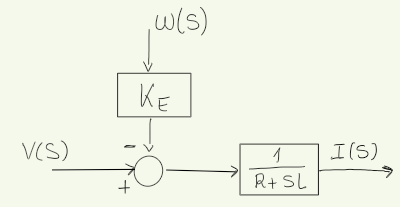

Raccogliendo $R_{a\;}$al denominatore, possiamo scrivere:


$${\textrm{tf}}_{\textrm{VI},\textrm{simple}} =G\left(s\right)=\frac{1}{R_a +{\textrm{sL}}_{a\;} }=\frac{1}{R_{a\;} \left(1+s\bullet \frac{L_a }{R_a }\right)}=\frac{1}{R_{a\;} \left(1+s\tau {\;}_e \right)}=\frac{1}{R_{a\;} }\bullet \frac{1}{\;1+s\tau_e }$$


    tf_V_I_simple = tf([1/m.Ra],[m.te,1]);
    m.tf_V_I_simple = tf_V_I_simple;

Per considerare anche l'apporto (negativo) della bemf, bisogna ampliare il modello, introducendo anche la modellizzazione della parte meccanica del motore, ovvero la parte che va legare la corrente alla coppia e successivamente alla velocità $\omega \ldotp$

Per trovare la funzione di trasferimento $\frac{V}{I}$, vediamo il sistema in questa ottica (considerando $C_{r\;}$nulla):

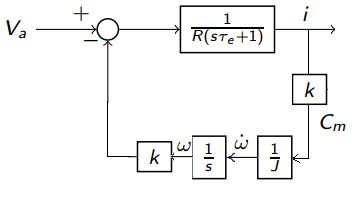

Dalla teoria del controllo, sappiamo che la funzione di trasferimento completa in anello chiuso può essere scritta come:


$$G\left(s\right)=\frac{L\left(s\right)}{1+L\left(s\right)H\left(s\right)}$$



$$L\left(s\right)=\frac{1}{R_a \left(s\tau {\;}_{e\;} +1\right)},\;\;H\left(s\right)=\frac{k^{2\;} }{J_m s}$$


Perciò:


$$G\left(s\right)=\frac{\frac{1}{R_a \left(s\tau {\;}_{e\;} +1\right)}}{1+\frac{1}{R_a \left(s\tau {\;}_{e\;} +1\right)}\bullet \frac{k^{2\;} }{J_{m\;} s}\;}=\ldotp \ldotp \ldotp =\frac{J_m s}{R_{a\;} J_{a\;} \tau {\;}_e s^2 +R_{a\;} J_{m\;} s+k^2 }$$


Ricordando le equazioni $\tau_e =\frac{L_{a\;} }{R_{a\;} }$e $t_m =\frac{J_{m\;} R_a }{K^2 }$ e sostituendola nella precedente equazioni, andiamo ad ottenere:


$${\textrm{tf}}_{\textrm{VI},\textrm{complete}} =G\left(s\right)=\frac{\frac{\tau {\;}_m \;}{R_a }s}{\tau_m \tau {\;}_e s^2 +\tau {\;}_m s+1}$$


    tf_V_I = tf([m.tm/m.Ra, 0],[m.tm*m.te,m.tm,1]);
    m.tf_V_I = tf_V_I;

Considerando invece il sistema completo

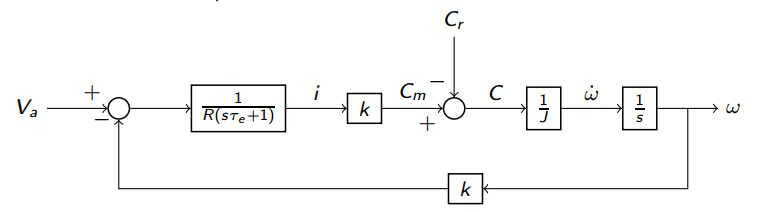

La funzione di trasferimento risulta essere (considerando nuovamente $C_{r\;} =0$)


$${\textrm{tf}}_{V\omega } =G\left(s\right)=\frac{\frac{1}{k}}{\tau {\;}_{m\;} \tau_e s^{2\;} +\tau {\;}_m s+1}$$


    tf_V_w = tf([1/m.K],[m.te*m.tm, m.tm, 1]);
    set(tf_V_w,'Name',['motore', m.name], 'InputName', 'Va', 'OutputName', 'Omega');
    
    m.tf_V_w = tf_V_w;
    

Andiamo a plottare alcune informazioni relative alla modellizzazione del motore

    figure('Name', 'Posizione dei poli');
    pzmap(tf_V_I_simple);
    hold on;
    pzmap(tf_V_I);
    legend('Modello semplificato','Modello completo');
    
    figure('Name', 'Modello elettrico del motore');
    h = bodeplot(tf_V_I_simple);
    hold on;
    bodeplot(tf_V_I);
    setoptions(h,'FreqUnits','Hz');
    legend('Modello semplificato','Modello completo');
    
    figure('Name', 'Risposta al gradino');
    step(tf_V_I_simple);
    hold on;
    step(tf_V_I);
    legend('Modello semplificato','Modello completo');
    hold off
end